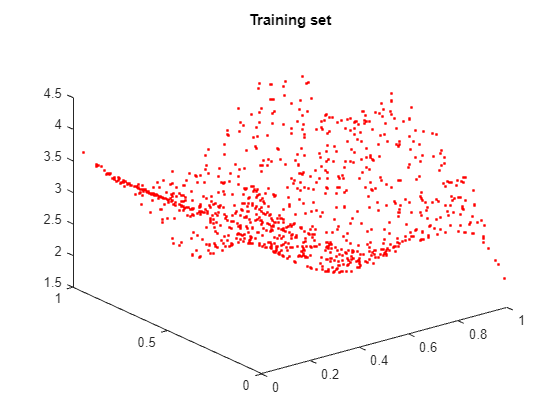

clear
clc
close all
load("Data_Problem1_regression.mat");

Tnew = (8*T1 + 7 *T2 + 7*T3 + 6*T4 + 4*T5)/(8+7+7+6+4);

dataset1 = zeros(1000,3);
dataset2 = zeros(1000,3);
dataset3 = zeros(1000,3);


for i  = 1:3
    for j = 1:1000
        index = randi([1,size(X1,1)]);
        dataset1(j,i) = X1(index);
        dataset2(j,i) = X2(index);
        dataset3(j,i) = Tnew(index);
    end
end


plot3(dataset1(:,1),dataset2(:,1),dataset3(:,1),'r.');
title('Training set');

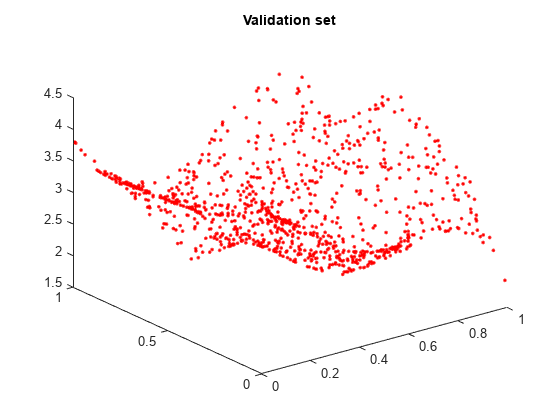

plot3(dataset1(:,2),dataset2(:,2),dataset3(:,2),'r.');
title('Validation set');

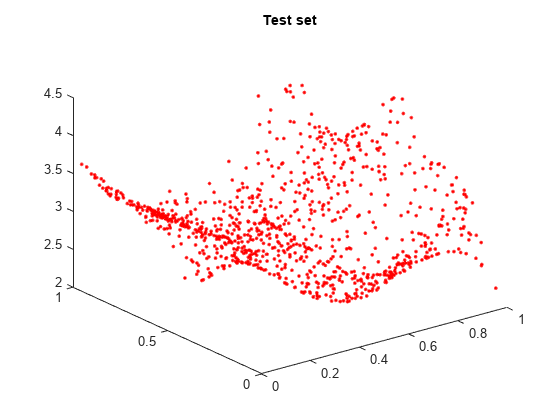

plot3(dataset1(:,3),dataset2(:,3),dataset3(:,3),'r.');
title('Test set');


x = dataset1(:,1);
y = dataset2(:,1); 
z = dataset3(:,1);

del = delaunay(x,y);

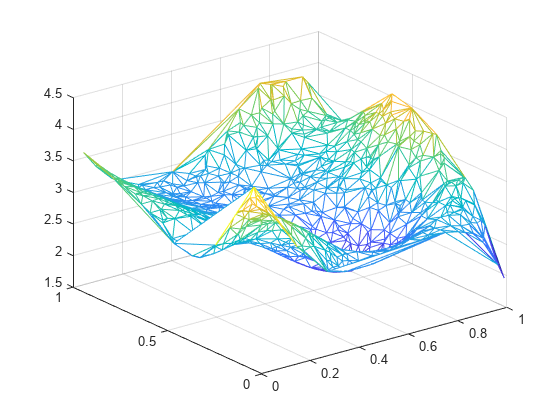

trimesh(del, x, y, z);

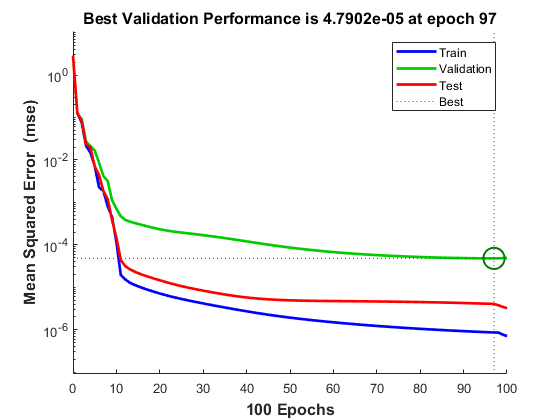



numN = 20;
%Training 1
trainAlg1 = 'trainlm';
net1 = feedforwardnet([numN, numN/2],trainAlg1);
net1.trainParam.epochs = 100;
Xcomb = horzcat(dataset1(:,1), dataset2(:,1));

net1=configure(net1,Xcomb',dataset3(:,1)');

[net1, tr] = train(net1, Xcomb', dataset3(:,1)');

plotperform(tr)

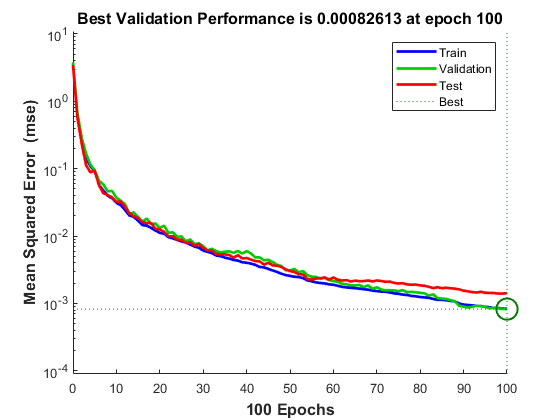


%Training 2
trainAlg2 = 'trainbfg';
net2 = feedforwardnet([numN, numN/2],trainAlg2);
net2.trainParam.epochs = 100;
Xcomb = horzcat(dataset1(:,1), dataset2(:,1));

net2=configure(net2,Xcomb',dataset3(:,1)');

[net2, tr] = train(net2, Xcomb', dataset3(:,1)');

plotperform(tr)

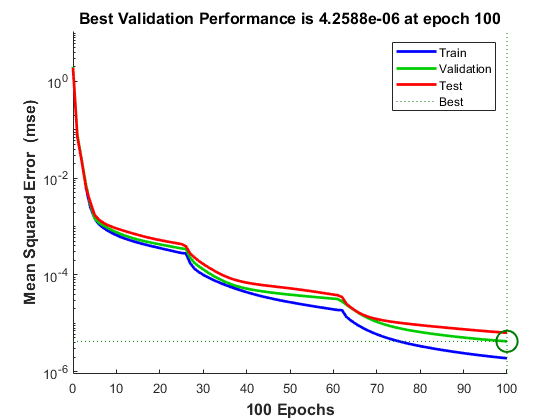


%Training 3
trainAlg3 = 'traingd';
net3 = feedforwardnet([numN, numN/2],trainAlg3);
net3.trainParam.epochs = 100;
Xcomb = horzcat(dataset1(:,1), dataset2(:,1));

net3=configure(net1,Xcomb',dataset3(:,1)');

[net3, tr] = train(net3, Xcomb', dataset3(:,1)');

plotperform(tr)

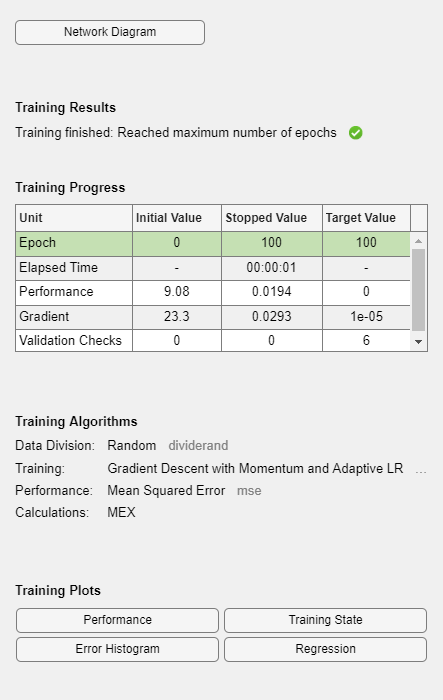

%Training 4
trainAlg4 = 'traingdx';
net4 = feedforwardnet([numN, numN/2],trainAlg4);
net4.trainParam.epochs = 100;
Xcomb = horzcat(dataset1(:,1), dataset2(:,1));

net4=configure(net4,Xcomb',dataset3(:,1)');

[net4, tr] = train(net4, Xcomb', dataset3(:,1)');

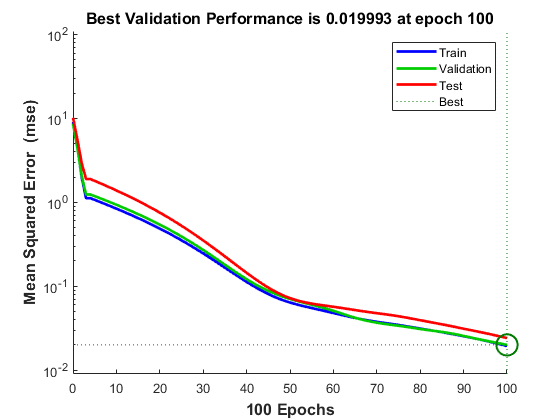

plotperform(tr)

Xcomb1 = horzcat(dataset1(:,2), dataset2(:,2))';


netVal1 = sim(net1,Xcomb1);
netVal2 = sim(net2,Xcomb1);
netVal3 = sim(net3,Xcomb1);
netVal4 = sim(net4,Xcomb1);
perform(net4,dataset3(:,2),netVal4')

ans = 0.0203

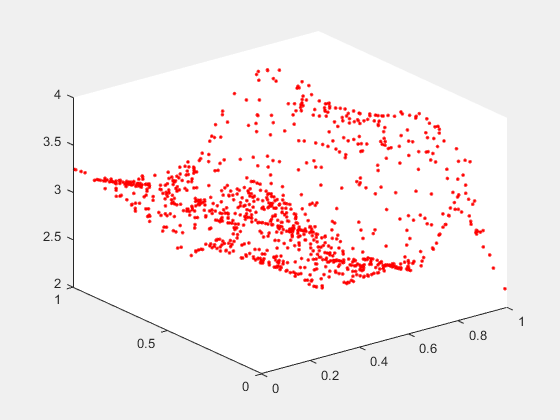

% Create scatteredInterpolant object
plot3(dataset1(:,2),dataset2(:,2),netVal4,'r.');


F1 = scatteredInterpolant(dataset1(:, 2), dataset2(:, 2), netVal1');

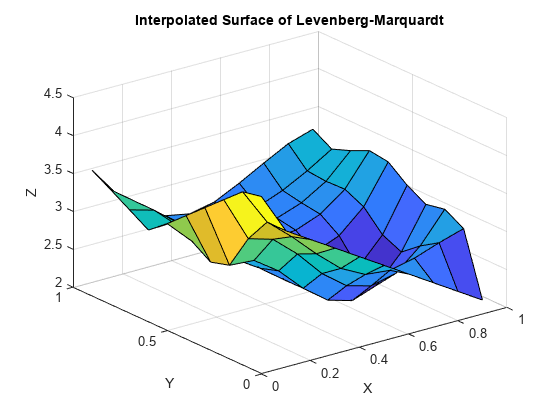

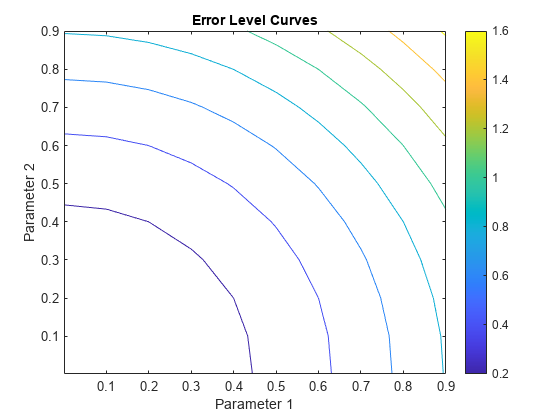


% Generate a grid of points for interpolation
[X, Y] = meshgrid(min(dataset1(:, 2)):0.1:max(dataset1(:, 2)), min(dataset2(:, 2)):0.1:max(dataset2(:, 2)));

% Evaluate the interpolant on the grid
Z1 = F1(X, Y);

% Plot the interpolated surface
figure;
surf(X, Y, Z1);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Interpolated Surface of Levenberg-Marquardt');


F2 = scatteredInterpolant(dataset1(:, 2), dataset2(:, 2), netVal2');

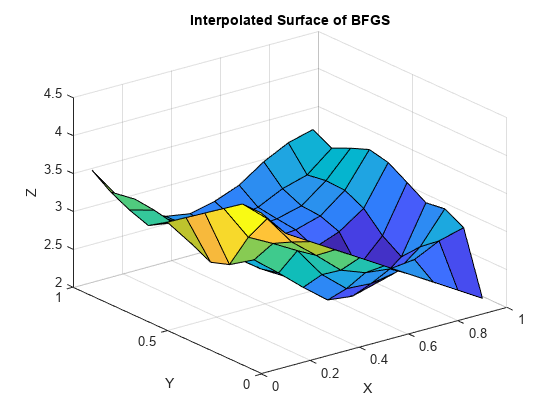


% Generate a grid of points for interpolation
[X, Y] = meshgrid(min(dataset1(:, 2)):0.1:max(dataset1(:, 2)), min(dataset2(:, 2)):0.1:max(dataset2(:, 2)));

% Evaluate the interpolant on the grid
Z2 = F2(X, Y);

% Plot the interpolated surface
figure;
surf(X, Y, Z2);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Interpolated Surface of BFGS');


F3 = scatteredInterpolant(dataset1(:, 2), dataset2(:, 2), netVal3');

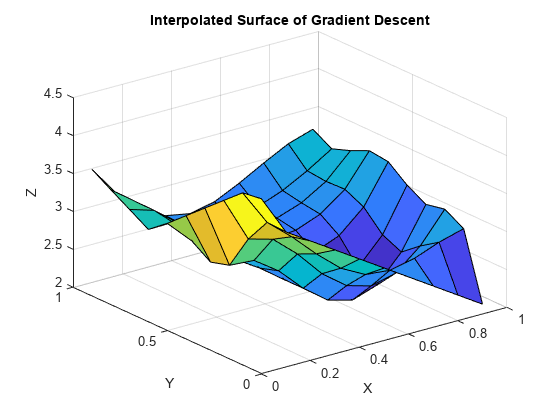


% Generate a grid of points for interpolation
[X, Y] = meshgrid(min(dataset1(:, 2)):0.1:max(dataset1(:, 2)), min(dataset2(:, 2)):0.1:max(dataset2(:, 2)));

% Evaluate the interpolant on the grid
Z3 = F3(X, Y);

% Plot the interpolated surface
figure;
surf(X, Y, Z3);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Interpolated Surface of Gradient Descent');


F4 = scatteredInterpolant(dataset1(:, 2), dataset2(:, 2), netVal4');

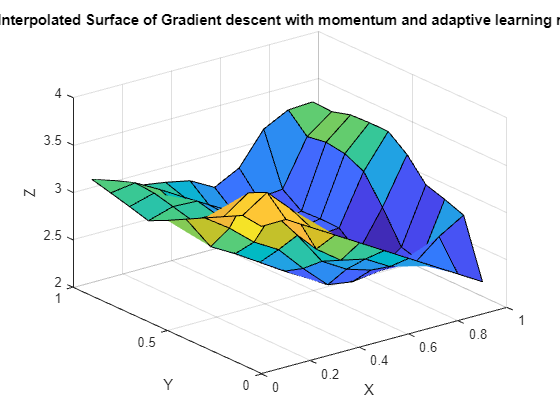


% Generate a grid of points for interpolation
[X, Y] = meshgrid(min(dataset1(:, 2)):0.1:max(dataset1(:, 2)), min(dataset2(:, 2)):0.1:max(dataset2(:, 2)));

% Evaluate the interpolant on the grid
Z4 = F4(X, Y);

% Plot the interpolated surface
figure;
surf(X, Y, Z4);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Interpolated Surface of Gradient descent with momentum and adaptive learning rate');

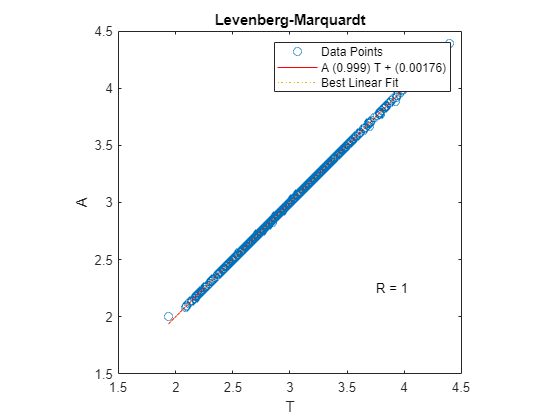


%Validate training 1
postregm(netVal1,dataset3(:,2)');
title(sprintf('Levenberg-Marquardt'));

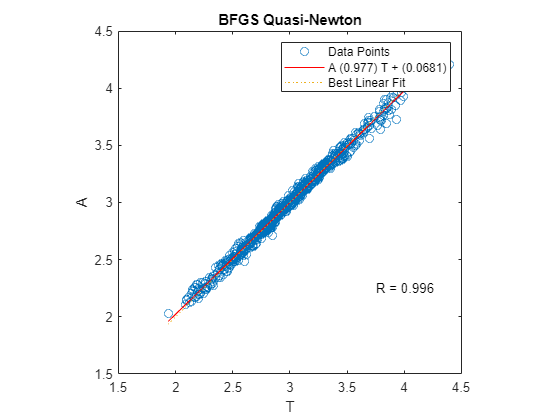


%Validate training 2
postregm(netVal2,dataset3(:,2)');
title(sprintf('BFGS Quasi-Newton'));

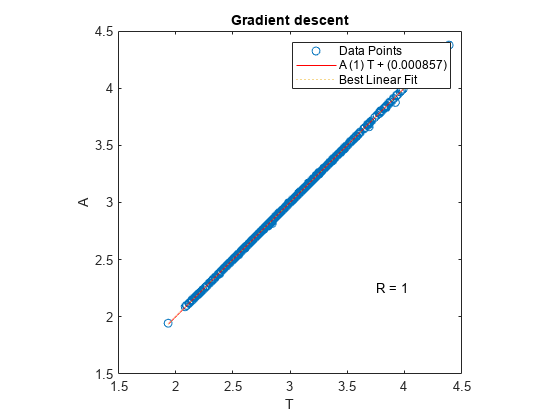


%Validate training 3
postregm(netVal3,dataset3(:,2)');
title(sprintf('Gradient descent'));

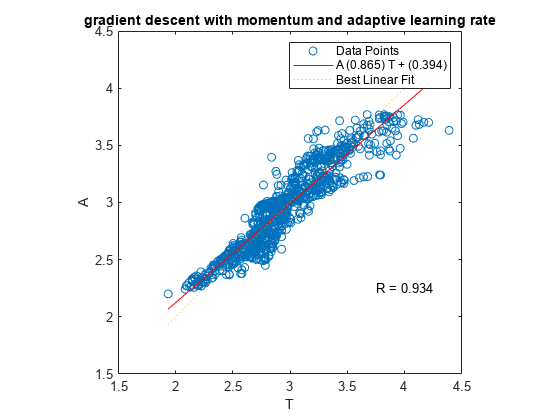


%Validate training 4
postregm(netVal4,dataset3(:,2)');
title(sprintf('gradient descent with momentum and adaptive learning rate'));